# The goal for this version is to introduce Phase variant LGN input

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo060521/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...currentVec(2)^2
    N_E,NnE,Size_E,...
    Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 13.651146 seconds.



C_EI_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 6.739481 seconds.



C_IE_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_E,NnE,Size_E,...
    Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 7.767392 seconds.



C_II_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.093044 seconds.



CMatAll = struct('C_EE_Fix',C_EE_Fix,...
                 'C_EI_Fix',C_EI_Fix,...
                 'C_IE_Fix',C_IE_Fix,...
                 'C_II_Fix',C_II_Fix);

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Placeholder for old BG session...

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

LFNFreq = 2; % 2Hz
tMod = 1e3/LFNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = tMod*rand(N_E,1);
PhaseFR = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);  
    AdjlgnE = PhaseFR(floor(PhaseE/MaxOnPhase)*ODNum + OD_E')';
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE./lambda_E_drive...
                      + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','CMatAll','-v7.3')
save([SaveFolder,'DriveWkSp_FixPreSynN_LowIto_EndPhase.mat'],'PhaseE');
clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 19.7439

FrINow = 73.1345

Elapsed time is 2.435338 seconds.


SampleInd = 3

FrENow = 16.8595

FrINow = 70.1723

Elapsed time is 4.319237 seconds.


SampleInd = 4

FrENow = 16.0654

FrINow = 68.4518

Elapsed time is 6.624445 seconds.


SampleInd = 5

FrENow = 16.8602

FrINow = 70.9492

Elapsed time is 8.407949 seconds.


SampleInd = 6

FrENow = 15.9633

FrINow = 68.8334

Elapsed time is 10.667578 seconds.


SampleInd = 7

FrENow = 16.0273

FrINow = 68.9629

Elapsed time is 12.420052 seconds.


SampleInd = 8

FrENow = 16.5836

FrINow = 70.4914

Elapsed time is 14.734357 seconds.


SampleInd = 9

FrENow = 15.9496

FrINow = 69.0970

Elapsed time is 16.449328 seconds.


SampleInd = 10

FrENow = 16.5927

FrINow = 70.4613

Elapsed time is 18.741905 seconds.


SampleInd = 11

FrENow = 17.0066

FrINow = 71.6753

Elapsed time is 20.624425 seconds.


SampleInd = 12

FrENow = 16.0684

FrINow = 69.4647

Elapsed time is 22.867523 seconds.


SampleInd = 13

FrENow = 15.8169

FrINow = 68.6600

Elapsed time is 24.661758 seconds.


SampleInd = 14

FrENow = 16.7871

FrINow = 71.0741

Elapsed time is 26.949325 seconds.


SampleInd = 15

FrENow = 16.2681

FrINow = 69.7769

Elapsed time is 28.815903 seconds.


SampleInd = 16

FrENow = 16.5226

FrINow = 70.1399

Elapsed time is 31.170854 seconds.


SampleInd = 17

FrENow = 16.1965

FrINow = 69.8670

Elapsed time is 33.054851 seconds.


SampleInd = 18

FrENow = 16.0067

FrINow = 68.9860

Elapsed time is 35.356028 seconds.


SampleInd = 19

FrENow = 16.5676

FrINow = 70.6232

Elapsed time is 37.199690 seconds.


SampleInd = 20

FrENow = 16.4899

FrINow = 70.3850

Elapsed time is 39.589140 seconds.


SampleInd = 21

FrENow = 16.5135

FrINow = 70.3688

Elapsed time is 41.494347 seconds.


Elapsed time is 41.495118 seconds.


SampleInd = 22

FrENow = 16.3115

FrINow = 69.9179

Elapsed time is 2.263815 seconds.


SampleInd = 23

FrENow = 16.2445

FrINow = 69.6589

Elapsed time is 3.998126 seconds.


SampleInd = 24

FrENow = 15.7285

FrINow = 68.2807

Elapsed time is 6.280909 seconds.


SampleInd = 25

FrENow = 16.3032

FrINow = 69.3629

Elapsed time is 8.035317 seconds.


SampleInd = 26

FrENow = 16.2483

FrINow = 69.4786

Elapsed time is 10.320984 seconds.


SampleInd = 27

FrENow = 16.8740

FrINow = 70.9978

Elapsed time is 12.169695 seconds.


SampleInd = 28

FrENow = 15.8528

FrINow = 68.8126

Elapsed time is 14.374715 seconds.


SampleInd = 29

FrENow = 17.2458

FrINow = 71.9482

Elapsed time is 16.162049 seconds.


SampleInd = 30

FrENow = 15.9869

FrINow = 69.1363

Elapsed time is 18.403351 seconds.


SampleInd = 31

FrENow = 16.8747

FrINow = 71.7378

Elapsed time is 20.231694 seconds.


SampleInd = 32

FrENow = 15.5594

FrINow = 68.1142

Elapsed time is 22.513900 seconds.


SampleInd = 33

FrENow = 16.4319

FrINow = 70.0775

Elapsed time is 24.297802 seconds.


SampleInd = 34

FrENow = 16.3938

FrINow = 69.8624

Elapsed time is 26.615114 seconds.


SampleInd = 35

FrENow = 16.3756

FrINow = 69.8023

Elapsed time is 28.446823 seconds.


SampleInd = 36

FrENow = 16.9014

FrINow = 71.2568

Elapsed time is 30.773383 seconds.


SampleInd = 37

FrENow = 16.8519

FrINow = 71.5667

Elapsed time is 32.572199 seconds.


SampleInd = 38

FrENow = 15.8444

FrINow = 68.8334

Elapsed time is 34.896861 seconds.


SampleInd = 39

FrENow = 15.5632

FrINow = 67.7812

Elapsed time is 36.713627 seconds.


SampleInd = 40

FrENow = 16.3115

FrINow = 69.6659

Elapsed time is 39.025957 seconds.


SampleInd = 41

FrENow = 16.8435

FrINow = 70.9793

Elapsed time is 40.897864 seconds.


Elapsed time is 40.898650 seconds.


SampleInd = 42

FrENow = 16.5150

FrINow = 70.2255

Elapsed time is 2.330635 seconds.


SampleInd = 43

FrENow = 17.1270

FrINow = 72.0083

Elapsed time is 4.183123 seconds.


SampleInd = 44

FrENow = 15.4976

FrINow = 67.8391

Elapsed time is 6.475844 seconds.


SampleInd = 45

FrENow = 15.8314

FrINow = 68.5813

Elapsed time is 8.344284 seconds.


SampleInd = 46

FrENow = 16.3451

FrINow = 69.7745

Elapsed time is 10.688004 seconds.


SampleInd = 47

FrENow = 16.5524

FrINow = 70.2879

Elapsed time is 12.511524 seconds.


SampleInd = 48

FrENow = 15.7522

FrINow = 68.2992

Elapsed time is 14.785295 seconds.


SampleInd = 49

FrENow = 17.4257

FrINow = 72.3968

Elapsed time is 16.614825 seconds.


SampleInd = 50

FrENow = 16.1210

FrINow = 69.6219

Elapsed time is 18.910704 seconds.


SampleInd = 51

FrENow = 16.1721

FrINow = 69.7584

Elapsed time is 20.769033 seconds.


SampleInd = 52

FrENow = 16.8480

FrINow = 70.6949

Elapsed time is 23.044641 seconds.


SampleInd = 53

FrENow = 16.2483

FrINow = 70.1376

Elapsed time is 24.841079 seconds.


SampleInd = 54

FrENow = 15.3041

FrINow = 67.0367

Elapsed time is 27.135426 seconds.


SampleInd = 55

FrENow = 17.2131

FrINow = 71.7586

Elapsed time is 29.065621 seconds.


SampleInd = 56

FrENow = 16.5767

FrINow = 70.6509

Elapsed time is 31.362497 seconds.


SampleInd = 57

FrENow = 16.1431

FrINow = 69.6358

Elapsed time is 33.206029 seconds.


SampleInd = 58

FrENow = 16.0395

FrINow = 69.2057

Elapsed time is 35.358640 seconds.


SampleInd = 59

FrENow = 16.7916

FrINow = 71.1851

Elapsed time is 37.186849 seconds.


SampleInd = 60

FrENow = 16.2910

FrINow = 69.8670

Elapsed time is 39.445047 seconds.


SampleInd = 61

FrENow = 16.4091

FrINow = 70.2786

Elapsed time is 41.276646 seconds.


Elapsed time is 41.277364 seconds.


SampleInd = 62

FrENow = 15.9938

FrINow = 68.8658

Elapsed time is 2.344964 seconds.


SampleInd = 63

FrENow = 16.3108

FrINow = 69.8763

Elapsed time is 4.259848 seconds.


SampleInd = 64

FrENow = 16.4426

FrINow = 69.9202

Elapsed time is 6.555944 seconds.


SampleInd = 65

FrENow = 16.1088

FrINow = 69.4670

Elapsed time is 8.424848 seconds.


SampleInd = 66

FrENow = 16.7505

FrINow = 70.7827

Elapsed time is 10.733618 seconds.


SampleInd = 67

FrENow = 16.0212

FrINow = 69.3074

Elapsed time is 12.630132 seconds.


SampleInd = 68

FrENow = 16.2986

FrINow = 69.5433

Elapsed time is 14.841170 seconds.


SampleInd = 69

FrENow = 16.5303

FrINow = 70.3295

Elapsed time is 16.690134 seconds.


SampleInd = 70

FrENow = 15.8505

FrINow = 68.6831

Elapsed time is 18.913263 seconds.


SampleInd = 71

FrENow = 16.7772

FrINow = 70.9862

Elapsed time is 20.723769 seconds.


SampleInd = 72

FrENow = 16.2666

FrINow = 69.5364

Elapsed time is 23.017158 seconds.


SampleInd = 73

FrENow = 17.0386

FrINow = 71.7447

Elapsed time is 24.918074 seconds.


SampleInd = 74

FrENow = 15.7392

FrINow = 68.4218

Elapsed time is 27.164073 seconds.


SampleInd = 75

FrENow = 16.3748

FrINow = 69.8162

Elapsed time is 29.024419 seconds.


SampleInd = 76

FrENow = 16.3443

FrINow = 69.7329

Elapsed time is 31.348775 seconds.


SampleInd = 77

FrENow = 16.2315

FrINow = 69.7260

Elapsed time is 33.122783 seconds.


SampleInd = 78

FrENow = 16.9029

FrINow = 71.3262

Elapsed time is 35.373904 seconds.


SampleInd = 79

FrENow = 16.2818

FrINow = 69.8370

Elapsed time is 37.197294 seconds.


SampleInd = 80

FrENow = 16.2026

FrINow = 69.6959

Elapsed time is 39.419289 seconds.


SampleInd = 81

FrENow = 16.5386

FrINow = 70.6278

Elapsed time is 41.216577 seconds.


Elapsed time is 41.217300 seconds.


SampleInd = 82

FrENow = 16.2887

FrINow = 69.8532

Elapsed time is 2.363386 seconds.


SampleInd = 83

FrENow = 15.9381

FrINow = 69.0901

Elapsed time is 4.144965 seconds.


SampleInd = 84

FrENow = 16.4624

FrINow = 70.3133

Elapsed time is 6.352831 seconds.


SampleInd = 85

FrENow = 17.0127

FrINow = 71.4094

Elapsed time is 8.160338 seconds.


SampleInd = 86

FrENow = 16.1203

FrINow = 69.6335

Elapsed time is 10.429321 seconds.


SampleInd = 87

FrENow = 15.7865

FrINow = 68.5120

Elapsed time is 12.250736 seconds.


SampleInd = 88

FrENow = 16.8999

FrINow = 71.0024

Elapsed time is 14.554022 seconds.


SampleInd = 89

FrENow = 16.6507

FrINow = 71.0140

Elapsed time is 16.324746 seconds.


SampleInd = 90

FrENow = 15.7468

FrINow = 68.6276

Elapsed time is 18.589393 seconds.


SampleInd = 91

FrENow = 16.1988

FrINow = 69.5271

Elapsed time is 20.423989 seconds.


SampleInd = 92

FrENow = 16.5127

FrINow = 70.2486

Elapsed time is 22.640529 seconds.


SampleInd = 93

FrENow = 16.6476

FrINow = 70.7619

Elapsed time is 24.460862 seconds.


SampleInd = 94

FrENow = 15.5037

FrINow = 67.6703

Elapsed time is 26.683989 seconds.


SampleInd = 95

FrENow = 16.1843

FrINow = 69.4508

Elapsed time is 28.480710 seconds.


SampleInd = 96

FrENow = 16.2003

FrINow = 69.4069

Elapsed time is 30.769231 seconds.


SampleInd = 97

FrENow = 16.9121

FrINow = 71.0186

Elapsed time is 32.638574 seconds.


SampleInd = 98

FrENow = 16.0273

FrINow = 69.2982

Elapsed time is 34.873388 seconds.


SampleInd = 99

FrENow = 17.3320

FrINow = 72.6327

Elapsed time is 36.768945 seconds.


SampleInd = 100

FrENow = 16.0715

FrINow = 69.4369

Elapsed time is 39.055050 seconds.


SampleInd = 101

FrENow = 16.0761

FrINow = 69.4624

Elapsed time is 40.885538 seconds.


Elapsed time is 40.886350 seconds.


SampleInd = 102

FrENow = 15.0015

FrINow = 66.3799

Elapsed time is 2.234921 seconds.


SampleInd = 103

FrENow = 17.3129

FrINow = 72.0268

Elapsed time is 4.188547 seconds.


SampleInd = 104

FrENow = 16.6240

FrINow = 70.5191

Elapsed time is 6.453845 seconds.


SampleInd = 105

FrENow = 15.9023

FrINow = 68.6738

Elapsed time is 8.185977 seconds.


SampleInd = 106

FrENow = 15.8985

FrINow = 68.7987

Elapsed time is 10.374123 seconds.


SampleInd = 107

FrENow = 17.3868

FrINow = 72.4014

Elapsed time is 12.277859 seconds.


SampleInd = 108

FrENow = 16.0585

FrINow = 69.4462

Elapsed time is 14.487209 seconds.


SampleInd = 109

FrENow = 16.5813

FrINow = 70.3758

Elapsed time is 16.352849 seconds.


SampleInd = 110

FrENow = 15.8307

FrINow = 68.6946

Elapsed time is 18.564414 seconds.


SampleInd = 111

FrENow = 16.7894

FrINow = 71.0487

Elapsed time is 20.412102 seconds.


SampleInd = 112

FrENow = 15.4031

FrINow = 67.6124

Elapsed time is 22.523542 seconds.


SampleInd = 113

FrENow = 16.2125

FrINow = 69.4554

Elapsed time is 24.390083 seconds.


SampleInd = 114

FrENow = 16.0418

FrINow = 68.7178

Elapsed time is 26.602552 seconds.


SampleInd = 115

FrENow = 17.0744

FrINow = 71.4950

Elapsed time is 28.341820 seconds.


SampleInd = 116

FrENow = 16.0867

FrINow = 69.3676

Elapsed time is 30.545288 seconds.


SampleInd = 117

FrENow = 15.8863

FrINow = 68.7640

Elapsed time is 32.325951 seconds.


SampleInd = 118

FrENow = 16.6019

FrINow = 70.4451

Elapsed time is 34.643351 seconds.


SampleInd = 119

FrENow = 16.1934

FrINow = 69.6219

Elapsed time is 36.422636 seconds.


SampleInd = 120

FrENow = 16.8084

FrINow = 71.0441

Elapsed time is 38.645308 seconds.


SampleInd = 121

FrENow = 16.3771

FrINow = 70.1653

Elapsed time is 40.466791 seconds.


Elapsed time is 40.467500 seconds.


SampleInd = 122

FrENow = 16.4594

FrINow = 70.4636

Elapsed time is 2.285322 seconds.


SampleInd = 123

FrENow = 15.7385

FrINow = 68.3778

Elapsed time is 4.122183 seconds.


SampleInd = 124

FrENow = 17.0309

FrINow = 71.2452

Elapsed time is 6.473298 seconds.


SampleInd = 125

FrENow = 16.2772

FrINow = 69.8971

Elapsed time is 8.357400 seconds.


SampleInd = 126

FrENow = 16.2696

FrINow = 69.5780

Elapsed time is 10.676692 seconds.


SampleInd = 127

FrENow = 17.3213

FrINow = 72.3806

Elapsed time is 12.568489 seconds.


SampleInd = 128

FrENow = 15.6280

FrINow = 68.3270

Elapsed time is 14.763225 seconds.


SampleInd = 129

FrENow = 16.7993

FrINow = 71.0394

Elapsed time is 16.579113 seconds.


SampleInd = 130

FrENow = 16.5554

FrINow = 70.6255

Elapsed time is 18.901600 seconds.


SampleInd = 131

FrENow = 16.6705

FrINow = 71.1204

Elapsed time is 20.749936 seconds.


SampleInd = 132

FrENow = 15.7080

FrINow = 68.4102

Elapsed time is 23.030375 seconds.


SampleInd = 133

FrENow = 16.4419

FrINow = 70.0520

Elapsed time is 24.841048 seconds.


SampleInd = 134

FrENow = 16.3070

FrINow = 69.5687

Elapsed time is 27.082572 seconds.


SampleInd = 135

FrENow = 15.8985

FrINow = 68.6854

Elapsed time is 28.914462 seconds.


SampleInd = 136

FrENow = 16.7414

FrINow = 70.7388

Elapsed time is 31.241290 seconds.


SampleInd = 137

FrENow = 16.1660

FrINow = 69.6635

Elapsed time is 33.082185 seconds.


SampleInd = 138

FrENow = 15.6142

FrINow = 68.3223

Elapsed time is 35.237639 seconds.


SampleInd = 139

FrENow = 17.0378

FrINow = 71.5412

Elapsed time is 37.123705 seconds.


SampleInd = 140

FrENow = 16.4579

FrINow = 70.2000

Elapsed time is 39.411452 seconds.


SampleInd = 141

FrENow = 16.3672

FrINow = 70.0867

Elapsed time is 41.236330 seconds.


Elapsed time is 41.237031 seconds.


SampleInd = 142

FrENow = 16.2399

FrINow = 69.6520

Elapsed time is 2.309679 seconds.


SampleInd = 143

FrENow = 15.9617

FrINow = 68.7340

Elapsed time is 4.141848 seconds.


SampleInd = 144

FrENow = 15.9747

FrINow = 68.8103

Elapsed time is 6.365507 seconds.


SampleInd = 145

FrENow = 16.4640

FrINow = 70.1769

Elapsed time is 8.133750 seconds.


SampleInd = 146

FrENow = 16.2955

FrINow = 69.6080

Elapsed time is 10.435313 seconds.


SampleInd = 147

FrENow = 16.1340

FrINow = 69.2034

Elapsed time is 12.250999 seconds.


SampleInd = 148

FrENow = 16.8640

FrINow = 71.1967

Elapsed time is 14.572670 seconds.


SampleInd = 149

FrENow = 16.5645

FrINow = 70.7434

Elapsed time is 16.438655 seconds.


SampleInd = 150

FrENow = 16.0875

FrINow = 69.2311

Elapsed time is 18.631354 seconds.


SampleInd = 151

FrENow = 16.3717

FrINow = 70.0867

Elapsed time is 20.444932 seconds.


SampleInd = 152

FrENow = 16.3100

FrINow = 69.5433

Elapsed time is 22.763036 seconds.


SampleInd = 153

FrENow = 16.8358

FrINow = 71.2522

Elapsed time is 24.672402 seconds.


SampleInd = 154

FrENow = 16.4312

FrINow = 70.3388

Elapsed time is 26.999158 seconds.


SampleInd = 155

FrENow = 15.7240

FrINow = 68.3709

Elapsed time is 28.798083 seconds.


SampleInd = 156

FrENow = 16.1149

FrINow = 68.9721

Elapsed time is 31.011300 seconds.


SampleInd = 157

FrENow = 17.0713

FrINow = 71.8673

Elapsed time is 32.920438 seconds.


SampleInd = 158

FrENow = 15.8970

FrINow = 68.7016

Elapsed time is 35.184014 seconds.


SampleInd = 159

FrENow = 16.1347

FrINow = 69.3514

Elapsed time is 36.985703 seconds.


SampleInd = 160

FrENow = 16.9303

FrINow = 71.5852

Elapsed time is 39.248068 seconds.


SampleInd = 161

FrENow = 16.1759

FrINow = 69.6867

Elapsed time is 41.094747 seconds.


Elapsed time is 41.095479 seconds.


SampleInd = 162

FrENow = 15.9488

FrINow = 68.6946

Elapsed time is 2.289429 seconds.


SampleInd = 163

FrENow = 16.2041

FrINow = 69.5757

Elapsed time is 4.137365 seconds.


SampleInd = 164

FrENow = 16.0067

FrINow = 68.9074

Elapsed time is 6.368925 seconds.


SampleInd = 165

FrENow = 16.0425

FrINow = 68.8496

Elapsed time is 8.204092 seconds.


SampleInd = 166

FrENow = 16.3946

FrINow = 69.8948

Elapsed time is 10.434868 seconds.


SampleInd = 167

FrENow = 17.1239

FrINow = 71.8673

Elapsed time is 12.372027 seconds.


SampleInd = 168

FrENow = 16.0761

FrINow = 69.4254

Elapsed time is 14.664766 seconds.


SampleInd = 169

FrENow = 16.9067

FrINow = 71.3909

Elapsed time is 16.584776 seconds.


SampleInd = 170

FrENow = 15.7202

FrINow = 68.3408

Elapsed time is 18.862456 seconds.


SampleInd = 171

FrENow = 16.3763

FrINow = 70.1353

Elapsed time is 20.707440 seconds.


SampleInd = 172

FrENow = 15.9785

FrINow = 69.2727

Elapsed time is 22.997559 seconds.


SampleInd = 173

FrENow = 16.2353

FrINow = 69.4762

Elapsed time is 24.861150 seconds.


SampleInd = 174

FrENow = 16.1645

FrINow = 69.0970

Elapsed time is 27.123005 seconds.


SampleInd = 175

FrENow = 16.6880

FrINow = 70.5561

Elapsed time is 28.921525 seconds.


SampleInd = 176

FrENow = 16.0219

FrINow = 69.2311

Elapsed time is 31.178103 seconds.


SampleInd = 177

FrENow = 16.5249

FrINow = 70.3295

Elapsed time is 32.964253 seconds.


SampleInd = 178

FrENow = 15.8726

FrINow = 68.6831

Elapsed time is 35.075696 seconds.


SampleInd = 179

FrENow = 16.8793

FrINow = 71.1019

Elapsed time is 36.915381 seconds.


SampleInd = 180

FrENow = 15.6462

FrINow = 68.3478

Elapsed time is 39.169414 seconds.


SampleInd = 181

FrENow = 17.3266

FrINow = 72.6211

Elapsed time is 41.069389 seconds.


Elapsed time is 41.070092 seconds.


SampleInd = 182

FrENow = 15.6821

FrINow = 68.4357

Elapsed time is 2.310191 seconds.


SampleInd = 183

FrENow = 16.6095

FrINow = 70.3110

Elapsed time is 4.218857 seconds.


SampleInd = 184

FrENow = 16.2925

FrINow = 69.6936

Elapsed time is 6.513664 seconds.


SampleInd = 185

FrENow = 16.0288

FrINow = 69.0646

Elapsed time is 8.330581 seconds.


SampleInd = 186

FrENow = 16.4213

FrINow = 70.1191

Elapsed time is 10.580593 seconds.


SampleInd = 187

FrENow = 16.7688

FrINow = 70.8752

Elapsed time is 12.430894 seconds.


SampleInd = 188

FrENow = 16.1599

FrINow = 69.4485

Elapsed time is 14.665156 seconds.


SampleInd = 189

FrENow = 16.3695

FrINow = 70.1815

Elapsed time is 16.538836 seconds.


SampleInd = 190

FrENow = 16.7779

FrINow = 71.0071

Elapsed time is 18.779837 seconds.


SampleInd = 191

FrENow = 16.8846

FrINow = 71.4718

Elapsed time is 20.634767 seconds.


SampleInd = 192

FrENow = 16.0951

FrINow = 69.5895

Elapsed time is 22.876323 seconds.


SampleInd = 193

FrENow = 16.3656

FrINow = 69.7098

Elapsed time is 24.747173 seconds.


SampleInd = 194

FrENow = 15.6600

FrINow = 68.0657

Elapsed time is 26.867273 seconds.


SampleInd = 195

FrENow = 16.3778

FrINow = 69.9341

Elapsed time is 28.644852 seconds.


SampleInd = 196

FrENow = 17.1856

FrINow = 71.9297

Elapsed time is 30.989426 seconds.


SampleInd = 197

FrENow = 16.4670

FrINow = 70.4359

Elapsed time is 32.747060 seconds.


SampleInd = 198

FrENow = 15.5578

FrINow = 67.7327

Elapsed time is 34.955222 seconds.


SampleInd = 199

FrENow = 16.9608

FrINow = 71.3978

Elapsed time is 36.823109 seconds.


SampleInd = 200

FrENow = 15.9831

FrINow = 69.2357

Elapsed time is 39.100055 seconds.


SampleInd = 201

FrENow = 16.5546

FrINow = 70.5191

Elapsed time is 40.961512 seconds.


Elapsed time is 40.962212 seconds.


Plot Spatial maps: load data

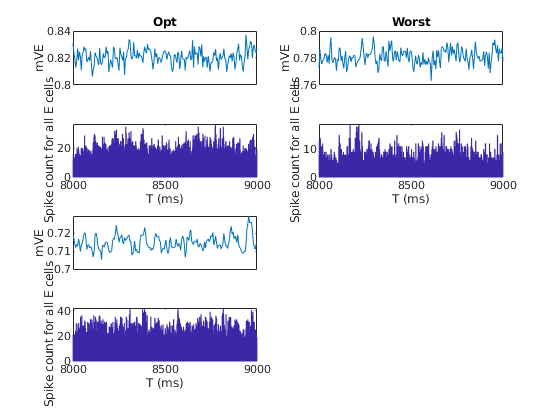

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
load([SaveFolder text],'CMatAll');
C_EE_Fix = CMatAll.C_EE_Fix;
C_EI_Fix = CMatAll.C_EI_Fix;
C_IE_Fix = CMatAll.C_IE_Fix;
C_II_Fix = CMatAll.C_II_Fix;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

% Check soome time dependency// cental hypercolum??
OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColE = NnE.X>=n_E_HC & NnE.X<=2*n_E_HC;
MidRowE = NnE.Y>=n_E_HC & NnE.Y<=2*n_E_HC;
MidHCE = MidColE & MidRowE;

MidColI = NnI.X>=n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

ShowWin = [8000 9000];
figure('Name','Domain Range')

OD1E = find(OptE & MidHCE);
OD1I = find(OptI & MidHCI);
[~,OD1E_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
[~,OD1I_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
subplot 423
hold on
hist(SpE(ismember(SpE(:,1),find(OptE & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

subplot 424
hist(SpE(ismember(SpE(:,1),find(find(WorstE & MidHCE))),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

subplot 427
hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
xlim(ShowWin)


subplot 426
plot(StatWin(1:WinNum),mVE(OPT(1),:))
xlim([8e3 10e3])
subplot 428
plot(StatWin(1:WinNum),mVE(OPT(1000),:))
xlim([8e3 10e3])
% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

Plot Spatial maps: Plot

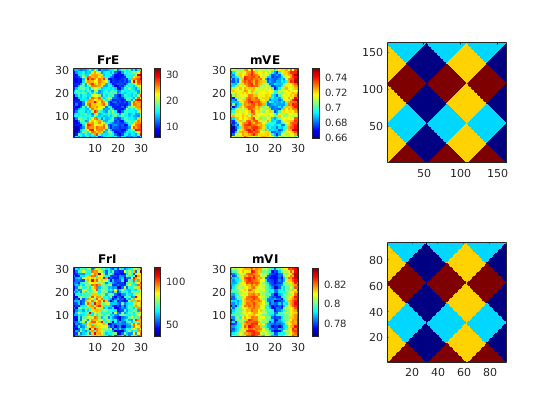

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot
OPT = find(OD_E == 1);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
tt = -T:dt:0;
hSpCount = figure('Name','SpCount')

hSpCount =   Figure (3: SpCount) with properties:

      Number: 3
        Name: 'SpCount'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


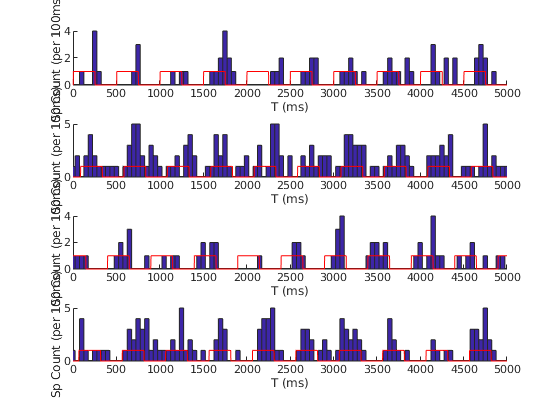

for subInd = 1:4
    subplot(4,1,subInd)
    NeuInd = OPT(subInd);
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd)+tt,tMod)/MaxOnPhase)));
    plot(tt+T,OnOff,'r')
    xlim([0 5000])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
end

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc
C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;
           MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
L6E_Pixel = zeros(size(mVEPixVec));
L6I_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
toc
% Err
FrErr = Fr_MFinv - Fr_L4;

EPixRange = [0 35];
IPixRange = [10 120]

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?